# **Segmentarea imaginilor**

## **Notiuni generale**

- **scop: divizarea** imaginii în părți (pe baza intensităților)

- **tipuri**: ==> **completă: **obțin regiun disjuncte cu obiectele din scenă (reușesc să separ obiectele de fundal)

-            ==> **parțială: **regiunile sunt omogene la nivel de luminozitate/culoare, separarea nu este însă completă

- **metode**: ==> bazate pe **cunoștințele globale **ale imaginii (**metode de prag **aplicate **histogramei**)

-                ==> bazate pe **muchii**

-                ==> bazate pe **regiuni**

###     a. Metode de prag

- alegerea unui nivel de gri (sau mai multe) prin care **delimităm** diferite regiuni sau **extragem** obiecte

#### BINARIZAREA

- alegem un **prag** pe baza **histogramei**

- crearea unei **imagini binare** pe baza acelui **prag**

        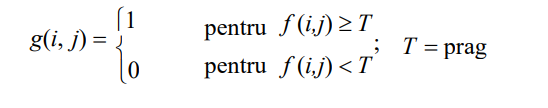

#### BAND-THRESHOLDING

- identific **obiectele** dacă nivelul de gri aparține unui **interval **și **binarizez**

        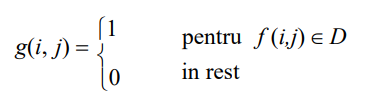

#### SEGMENTAREA CU PRAGURI MULTIPLE

- consider **mai multe intervale** de nivel de gri, care vor duce la existența mai multor **regiuni**

####         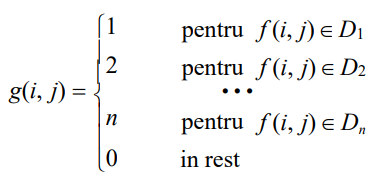

#### SEGMENTAREA CU SEMIPRAG

- **accentuez** **fundalul** prin alegerea unui **prag**

- pixeli ce depășesc nivelul stabilit rămân neschimbați.

###     b. SEGMENTAREA BAZATĂ PE MUCHII

- folosim algoritmi de detecție a muchiilor, alături de tehnici de îmbinare a acestora în contururi închise

#### OPERAȚII DE SEGMENTARE BAZATĂ PE MUCHII

- **umplere** ==> **imfill**

-     operația de colorare a unei zone de imagine ce conține pixeli cu același nivel de gri

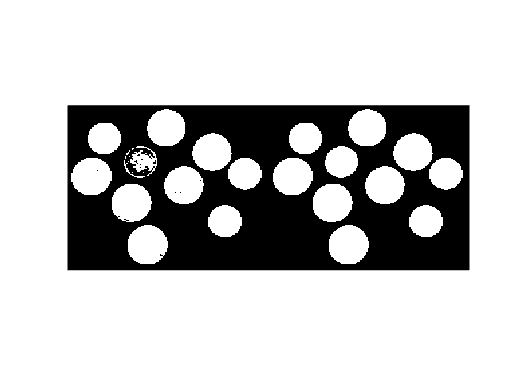

BW4 = imbinarize(imread('coins.png'));
BW5 = imfill(BW4,'holes');
imshowpair(BW4,BW5,'montage');

- **eroziune** ==> **imerode (**alături de** strel **sau** offsetstrel)**

-     operația de scădere a ariei unei zone de 1 dintr-o imagine binară urmărind frontiera acesteia pe interior, cu un element dat

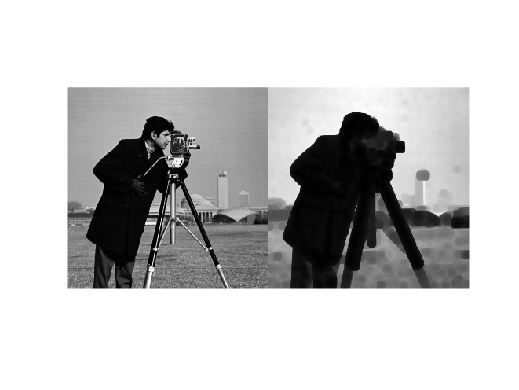

originalI = imread('cameraman.tif');
se = offsetstrel('ball',5,5);
erodedI = imerode(originalI,se);
imshowpair(originalI,erodedI,'montage')

- **dilatare** ==> **imdilate (**alături de** strel **sau** offsetstrel)**

-     operația inversă eroziunii, urmăriesc frontiera acesteia pe exterior, cu un element dat

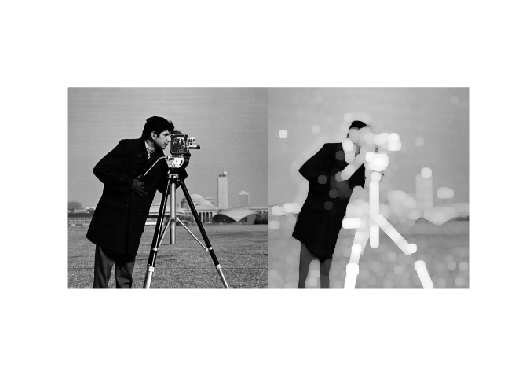

originalI = imread('cameraman.tif');
se = offsetstrel('ball',5,5);
dilatedI = imdilate(originalI,se);
imshowpair(originalI,dilatedI,'montage')

- **deschidere** ==> **imopen (**alături de** strel **sau** offsetstrel)**

- operația realizată prin eroziune și dilatare succesivă cu același element - elimină zonele albe dintr-o imagine binară 

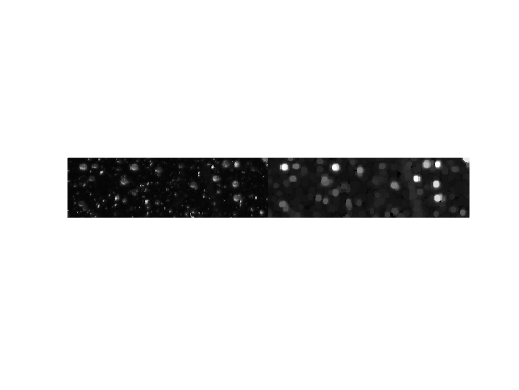

original = imread('snowflakes.png');
se = strel('disk',5);
afterOpening = imopen(original,se);
imshowpair(original,afterOpening,'montage')

- **inchidere** ==> **imclose (**alături de** strel **sau** offsetstrel)**

- operația realizată prin dilatare și eroziune succesivă cu același element - elimină din zonele albe "insulele de negru" dintr-o imagine binară 

original = imbinarize(imread('coins.png'));
se = strel('disk',10);
closeBW = imclose(im2bw(original),se);

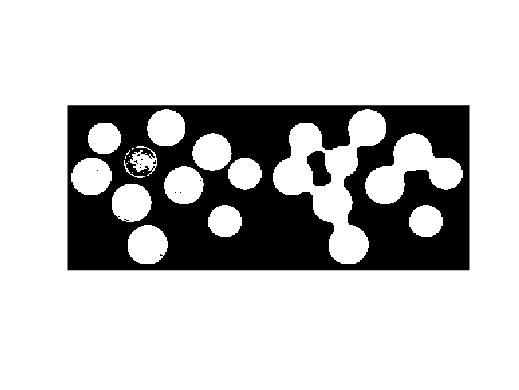

imshowpair(original,closeBW,'montage')

### **c**. Matlab functions

### im2bw** sau** imbinarize

- **realizează binarizarea imaginii **

- **poate fi apelată cu sau fără prag**

- **see *****help***

### graythresh

- **calculează nivelul de prag folosind metoa Otsu (determinarea unui prag optim pentru separarea unei imagini in doua "clase": fundal si obiecte)**

- **see *****help***

### **bwperim**

- **obținerea perimetrului dintr-o imagine binara**

- **see *****help***

## Exemplul

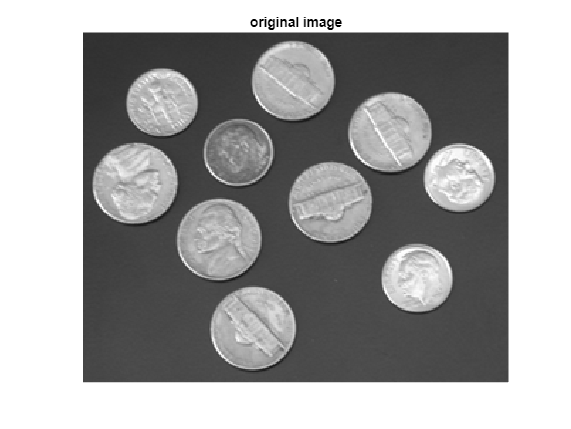

%clc, clear, close all;
I = imread("coins.png");
figure, imshow(I), title('original image');

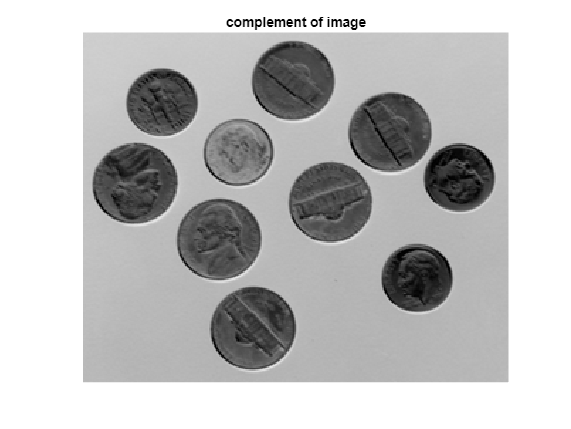

Ic = imcomplement(I);
BW = im2bw(Ic, graythresh(Ic));
figure, imshow(Ic), title('complement of image');

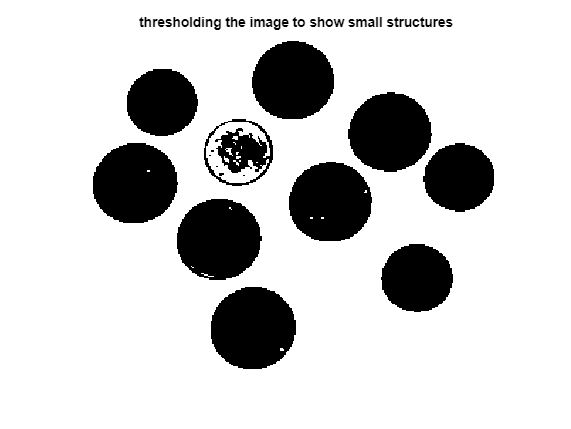

figure, imshow(BW);
title('thresholding the image to show small structures');

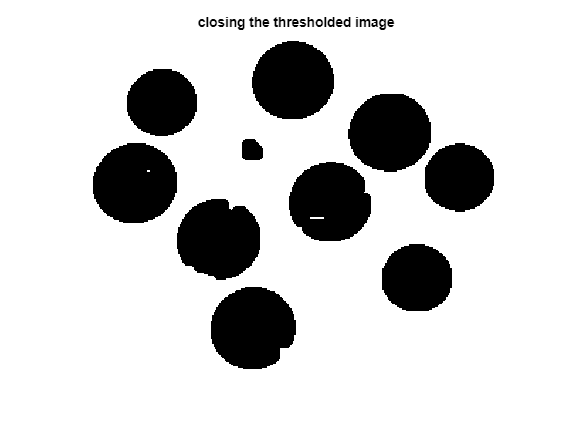

se = strel('disk', 6);
BWc = imclose(BW, se);
BWco = imopen(BWc, se);
figure, imshow(BWc), title('closing the thresholded image');

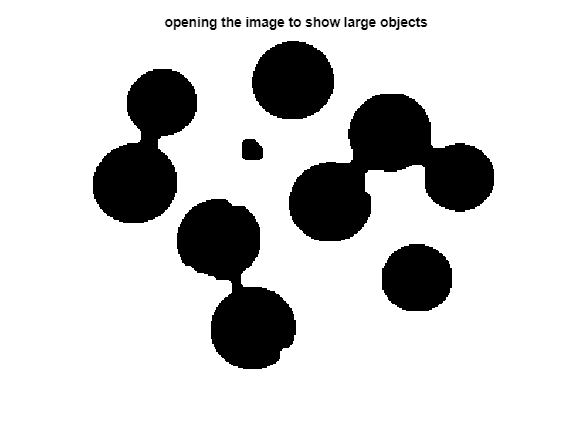

figure, imshow(BWco);
title('opening the image to show large objects');

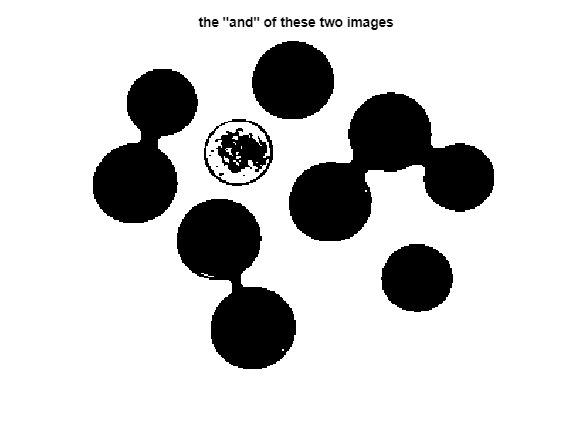

mask = BW & BWco;
figure, imshow(mask), title('the "and" of these two images');

## EXERCITII

% 4.5 Sa se aplice operatia de segmentare pe imaginea L7_image_04.png, iar
% fiecare dintre obiectele identificate sa fie evidentiat cu o alta culoare

##